# Exercícios

clear all;
clc;
close all;



## Sinal em análise g(t)

T0= 1                          % período

T0 = 1

f0 = 1/T0

f0 = 1

w0 = 2*pi*f0

w0 = 6.2832



g = @(t) (exp(-t));
gnt = @(n,t) exp(-j*n*w0*t);


## Ex 3

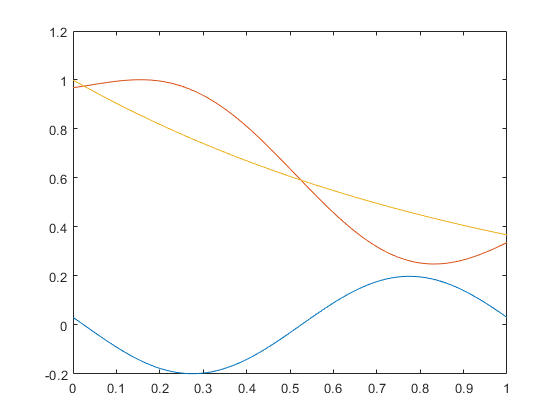

syms n t tempo
gt = (exp(-t));

c1= int(g(t) * gnt(1,t) ,t,0,T0) / ( int(gnt(1,t)* gnt(-1,t),t,0,T0) );
c_1 = int(g(t) * gnt(-1,t) ,t,0,T0) / ( int(gnt(-1,t) * gnt(1,t) ,t,0,T0) );

resc1 = eval(c1);
resc_1 = eval(c_1);

p1t = @(tempo) c1 * exp(-j*w0*tempo) + c_1*exp(j*w0*tempo);

r1t = @(tempo) g(tempo) - p1t(tempo);

tempo = [0:0.01:T0];

figure()
plot(tempo,p1t(tempo) ,tempo,r1t(tempo) ,tempo,g(tempo))

## Ex 4


c2= int(g(t) * gnt(2,t) ,t,0,T0) / ( int(gnt(2,t)* gnt(-2,t),t,0,T0) );
c_2 = int(g(t) * gnt(-2,t) ,t,0,T0) / ( int(gnt(-2,t) * gnt(2,t) ,t,0,T0) );

resc2 = eval(c2)

resc2 = 0.0040 - 0.0500i

resc_2 = eval(c_2)

resc_2 = 0.0040 + 0.0500i

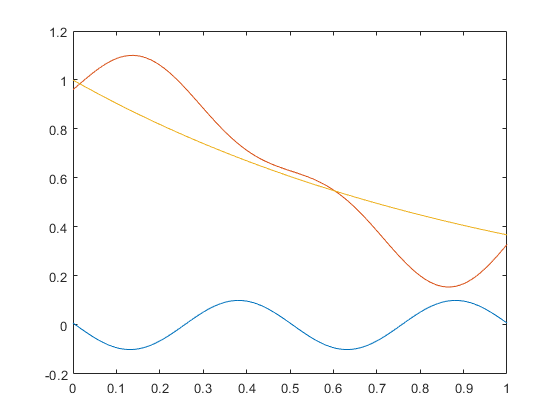


p2t = @(tempo) c2 * exp(-j*2*w0*tempo) + c_2*exp(j*2*w0*tempo);

r2t = @(tempo) g(tempo) - (p2t(tempo) + p1t(tempo));

tempo = [0:0.01:T0];

figure()

plot(tempo,p2t(tempo) ,tempo,r2t(tempo) ,tempo,g(tempo))


c2e = int(r1t(t)*gnt(2,t),t,0,T0) / ( int(gnt(2,t)* gnt(-2,t),t,0,T0) );
c_2e = int(r1t(t)*gnt(-2,t),t,0,T0) / ( int(gnt(-2,t)* gnt(2,t),t,0,T0) );
ce2 = eval(c2e)

ce2 = 0.0040 - 0.0500i

ce_2 = eval(c_2e)

ce_2 = 0.0040 + 0.0500i


% Os valores usando as diferentes equações é o mesmo, o que mostra
% que os valores de g(t) e r1 são praticamente iguais para n = 2.

## Ex 5

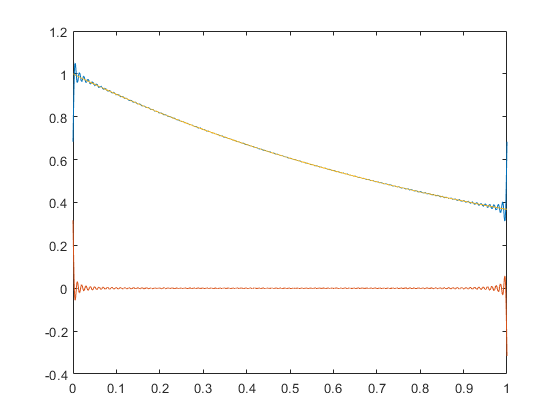


N = 100;
n=[-N:1:N];
tempoN = [0:1/(N*100):T0];

cn = int(gt*gnt,t,0,T0)/T0;

resc = eval(cn);


pn = 0;

for k=1:2*N+1
 pn = pn + resc(k)*exp(j*n(k)*w0*tempoN);
end

rnt = g(tempoN) - pn;

%%help cumsum

figure(1)

plot(tempoN,pn ,tempoN,rnt ,tempoN,g(tempoN))